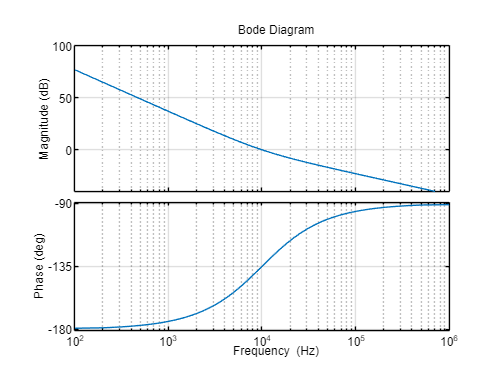

Vm = 5;             % PWM maximum value
Vref = 5;           % Reference value corresponding to maximum current
Pout = 7000;    % Maximum Power drawn from the converter
Vac = 325;          % Nominal RMS value of ac supply
fac = 50;           % Nominal frequency of the ac supply
Vout = 400;    % DC output of totem pole converter
fs_PFC = 100e3;      % Switching frequency
L = 500e-6;
C = 6.9636e-3;

kx = 0.01;                            % A set value of kx to have a constant control voltage at nominal current and maximum power 
Rs = 0.05;
vcontrol = Pout*2*Rs/kx/Vac^2;
s = tf('s');

opts = bodeoptions;
opts.freqUnits = 'Hz';
opts.grid = 'on';

Tui = Rs/Vm*Vout/s/L;
mag = abs(evalfr(Tui,1i*2*pi*10e3));
fci = 10e3;

wLi = 2*pi*fci*tan(45*pi/180);
Gci_inf = 1/mag/sqrt(1+(wLi/2/pi/fci)^2);
Gci = Gci_inf*(1+wLi/s);
Tci = Gci*Tui;
bode(Gci*Tui,opts);

y = Pout/Vout/vcontrol;
R = Vout*Vout/Pout;
H = 5/400;
Tuv = H*y*R/2/(1+s*R*C/2);
fcv = 20;
phase = 180/pi*angle(evalfr(Tuv,1i*2*pi*fcv));
% 
wLv = 2*pi*fcv*tan((180-60+phase)*pi/180);
mag = abs(evalfr(Tuv,1i*2*pi*fcv));
Gcv_inf = 1/mag/sqrt(1+(wLv/2/pi/fcv));
Gcv = Gcv_inf*(1+wLv/s);
Tcv = Gcv*Tuv;
